# DC 모터 속도 : 시스템 해석 (한글판)

원문 : Control Tutorials for MATLAB and Simulink — DC Motor Speed: System Analysis 한글 정리 : 제어시스템설계 · 충남대학교 자율운항시스템공학과

이 문서에서 하는 것

- DC 모터 속도 모델의 **개루프 응답**을 본다

- 사양을 만족하는지 따져 본다

- 2차 모델을 **1차로 줄여도 되는지**(모델 차수 축소) 확인한다

오늘 쓰는 MATLAB 명령 — `tf`, `step`, `pzmap`, `stepinfo`

clc; close all;
s = tf('s');

## 1. DC 모터는 어떻게 생겼나

DC 모터가 처음에 어려운 이유는 **전기와 기계가 맞물려 있기** 때문입니다.

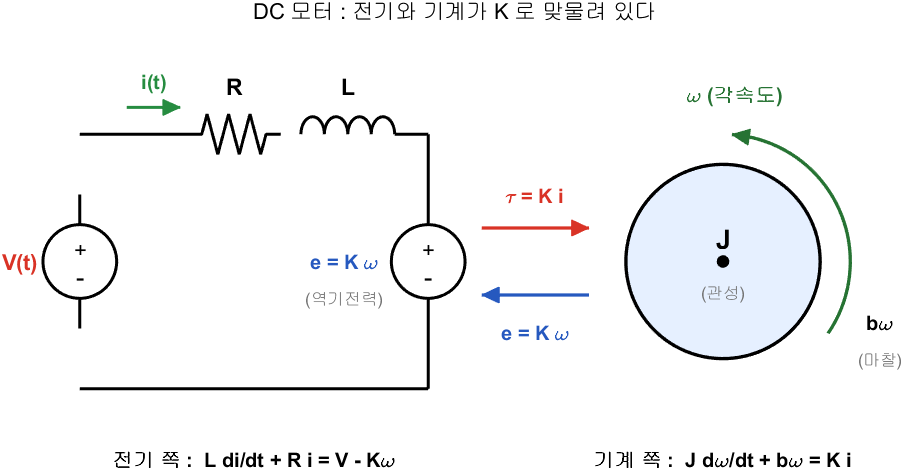

DC 모터 : 전기와 기계가 K 로 맞물려 있다

## 1-1. 식이 두 줄인 이유

맞물리는 곳이 둘입니다.

- **전기 **$\rightarrow$** 기계** : 전류가 흐르면 토크가 난다.  $\tau = K\,i$

- **기계 **$\rightarrow$** 전기** : 빨리 돌면 역기전력이 생긴다.  $e = K\,\omega$

그래서 지배방정식이 두 줄이고 서로를 참조합니다.


$$L\,\frac{di}{dt} + R\,i = V - K\,\omega \qquad (\text{키르히호프})$$



$$J\,\frac{d\omega}{dt} + b\,\omega = K\,i \qquad (\text{뉴턴, 회전})$$


두 식을 라플라스 변환하고 $I(s)$ 를 소거하면 전달함수가 나옵니다.


$$P(s) = \frac{\Omega(s)}{V(s)} = \frac{K}{(Js+b)(Ls+R) + K^2} \qquad \left[\frac{\mathrm{rad/s}}{\mathrm{V}}\right]$$


분모의 $K^2$ 항이 **역기전력이 만든 것**입니다. 빨리 돌수록 스스로 브레이크를 거는 셈이라 모터는 자연스럽게 안정합니다.

J = 0.01;  b = 0.1;  K = 0.01;  R = 1;  L = 0.5;
P_motor = K/((J*s + b)*(L*s + R) + K^2);

fprintf('=== 파라미터 ===\n');
fprintf('  J = %.3f kg m^2,  b = %.3f N m s,  K = %.3f,  R = %.1f ohm,  L = %.1f H\n\n', ...
        J, b, K, R, L);
fprintf('=== 전달함수 ===\n');
P_motor
fprintf('  극점 : %s\n', mat2str(round(pole(P_motor).', 4)));
fprintf('  DC 이득 : %.4f  (1 V 를 계속 넣으면 %.2f rad/s)\n\n', ...
        dcgain(P_motor), dcgain(P_motor));

## 2. 설계 사양

목표 속도 $1\,\mathrm{rad/s}$ 에 대해 요구는 이렇습니다.

- 정착시간 $2$ 초 미만

- 오버슈트 $5\%$ 미만

- 정상상태 오차 $1\%$ 미만

## 3. 개루프 응답 — 제어기 없이 그냥 넣어 보면

$1\,\mathrm{V}$ 를 계단으로 넣었을 때 어떻게 되는지 봅니다.

t = (0:0.01:5)';
y = step(P_motor, t);
info = stepinfo(P_motor);

figure;
plot(t, y, 'LineWidth', 2.5); hold on;
yline(1, 'k--', 'LineWidth', 1.5);
yline(dcgain(P_motor), 'r:', 'LineWidth', 1.5);
grid on; xlabel('시간 [s]'); ylabel('각속도 [rad s^{-1}]');
legend('개루프 응답', '목표 1 rad/s', '실제 도달값', 'Location','east');
title('제어기 없이 1 V 를 넣으면');

fprintf('=== 개루프 응답 ===\n');
fprintf('  도달 속도  %.4f rad/s   (목표 1)\n', y(end));
fprintf('  정착시간   %.3f s        (요구 2 s 미만)\n', info.SettlingTime);
fprintf('  오버슈트   %.2f %%        (요구 5 %% 미만)\n\n', info.Overshoot);

결과를 읽어 보면

- $1\,\mathrm{V}$ 를 넣어도 최대 $0.1\,\mathrm{rad/s}$ 밖에 안 나온다. **목표의 십분의 일**이다

- 정상상태에 도달하는 데 $2$ 초가 넘게 걸린다. 정착시간 사양도 못 맞춘다

즉 **제어기가 필요합니다.**

## 4. 모델 차수 줄이기 — 2차를 1차로 봐도 되는가

극점 위치와 응답 모양의 대응을 먼저 떠올려 두면 읽기가 쉽습니다.

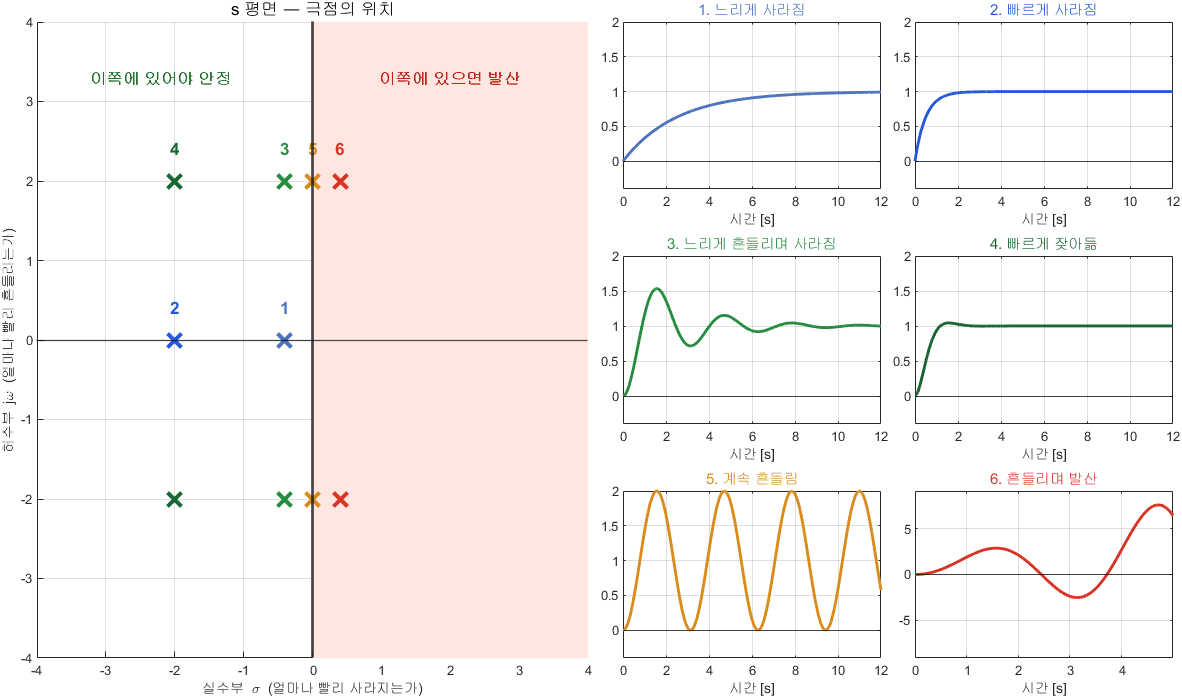

극점 위치와 응답 모양

이 전달함수는 2차입니다. 극점 위치를 보면 응답 성격을 예측할 수 있습니다.

figure;
pzmap(P_motor); grid on;
title('개루프 극점 (파란 x)');

p_ol = pole(P_motor);
fprintf('=== 극점 ===\n');
fprintf('  %s\n', mat2str(round(p_ol.', 4)));
fprintf('  두 극점의 비율 : %.2f 배\n\n', max(abs(p_ol))/min(abs(p_ol)));

그림에서 읽을 것

- 극점이 **둘 다 실수**다 ($s \approx -2$ 와 $s \approx -10$). 그래서 진동도 오버슈트도 없다. 앞의 응답 그림과 맞는다

- 한 극점이 다른 것보다 **약 5 배 더 왼쪽**에 있다

- 4주차에서 배운 **5배 규칙** 에 따르면, 느린 극점($-2$)이 응답을 지배한다

즉 이 시스템은 **1차처럼 행동합니다.**

## 4-1. 정말 그런지 확인

$s = -2$ 인 극점 하나만 남기고, 직류이득은 원래와 같게 맞춘 1차 모델을 만듭니다.

p_slow = max(real(p_ol));                 % 느린 극점 (허수축에 가까운 쪽)
tau = -1/p_slow;
P_1st = dcgain(P_motor)/(tau*s + 1);

fprintf('=== 1차 근사 ===\n');
P_1st
fprintf('  시정수 tau = %.3f s\n', tau);
fprintf('  1차 공식 정착시간 4*tau = %.3f s\n', 4*tau);
fprintf('  원래 2차 모델의 정착시간 = %.3f s\n\n', info.SettlingTime);

figure;
plot(t, step(P_motor, t), 'LineWidth', 2.5); hold on;
plot(t, step(P_1st, t), '--', 'LineWidth', 2);
grid on; xlabel('시간 [s]'); ylabel('각속도 [rad s^{-1}]');
legend('원래 2차 모델', '1차 근사', 'Location','southeast');
title('1차로 줄여도 거의 같다');

거의 겹칩니다. 차이가 나는 곳은 $t = 0$** 근처**뿐입니다.

- 2차 시스템은 $t = 0$ 에서 기울기가 $0$ 이다 (천천히 출발)

- 1차 근사는 $t = 0$ 에서 기울기가 이미 크다 (바로 출발)

이 차이는 빠른 극점($-10$)이 만드는 것이고, 아주 짧은 순간에만 보입니다.

## 5. 토크 상수 K 를 바꾸면

원문에서는 슬라이더로 $K$ 를 바꿉니다. $K$ 가 크다는 것은 **같은 전압으로 더 큰 토크를 낸다**는 뜻입니다.

특성방정식을 보면 $K$ 가 극점에 어떻게 들어가는지 보입니다.


$$(Js+b)(Ls+R) + K^2 = JL\,s^2 + (JR + bL)\,s + (bR + K^2) = 0$$



$$\Rightarrow \quad s = \frac{-(JR+bL) \pm \sqrt{(JR+bL)^2 - 4JL(bR+K^2)}}{2JL}$$


**판별식 안에만 **$K$** 가 들어 있습니다.** $K$ 를 키우면 판별식이 작아지므로 두 실근이 서로 가까워지고, 어느 값을 넘으면 **복소수가 되어 진동하기 시작합니다.**

fprintf('=== 토크 상수 K 를 바꿔 가며 ===\n');
fprintf('     K      판별식      극점                        성격\n');
fprintf('  ------  ----------  --------------------------  ------------\n');
for Kv = [0.01 0.05 0.1 0.2]
    a2 = J*L;  a1 = J*R + b*L;  a0 = b*R + Kv^2;
    disc = a1^2 - 4*a2*a0;
    rr = roots([a2 a1 a0]);
    if disc > 1e-9,  st2 = '실근 (진동 없음)';
    else,            st2 = '복소근 (진동)';
    end
    fprintf('  %6.2f  %10.4f  %-26s  %s\n', Kv, disc, mat2str(round(rr.',2)), st2);
end
fprintf('\n');

t5 = (0:0.005:3)';
figure;
hold on; grid on;
for Kv = [0.01 0.05 0.1 0.2]
    Pv = Kv/((J*s + b)*(L*s + R) + Kv^2);
    Pv = Pv/dcgain(Pv);              % 공평하게 비교하려고 크기를 맞춘다
    plot(t5, step(Pv, t5), 'LineWidth', 2, 'DisplayName', sprintf('K = %.2f', Kv));
end
yline(1, 'k--', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('각속도 (크기를 맞춘 값)');
legend('Location','southeast');
title('토크 상수를 키우면 빨라지다가 결국 진동한다');

**여기서 얻는 교훈**

- 모터를 "세게" 만들면 빨라지지만 **공짜가 아니다**. 어느 선을 넘으면 진동한다

- 이것은 나중에 배울 **이득을 키우면 진동한다** 는 성질과 정확히 같은 이야기다

- 물리 파라미터든 제어이득이든, 결국 **극점을 어디로 옮기는가**의 문제다

## 6. 정리

- DC 모터는 전기와 기계가 $K$ 로 맞물린 **2차 시스템**이다

- 개루프로는 $1\,\mathrm{V}$ 에 $0.1\,\mathrm{rad/s}$ 밖에 못 낸다. 제어기가 필요하다

- 두 극점의 비가 **5 배 이상**이면 느린 쪽만 남기고 **1차로 봐도 된다**

- 1차 근사의 정착시간은 $t_s = 4\tau$

- 파라미터를 바꾸는 것도 결국 **극점을 옮기는 일**이다

이 과목의 5 주차 내용과 그대로 이어집니다.